# Circuito equivalente de un transformador trifásico mediante ensayos de vacío y cortocircuito a tensión reducida

Autor: Ing. Pablo Cayuela - pablo.cayuela@gmail.com - UTN FRC - Córdoba - ARGENTINA

## Resumen

*Se describen los pasos del cálculo de los componentes del circuito equivalente de un transformador trifásico, a partir de las mediciones eléctricas en los ensayos de vacío y de cortocircuito a tensión reducida.*

## Objetivos de Aprendizaje

*Reconocer las magnitudes medidas en un ensayo de vacío y en un ensayo de cortocircuito a tensión reducida de un transformador trifásico.*

*Calcular los valores de los componentes pasivos del circuito equivalente de un transformador trifásico a partir de las magnitudes medidas en los ensayos de vacío y de cortocircuito a tensión reducida.*

## Sección 1: Conceptos 

### Características eléctricas de un transformador trifásico

Se tiene un transformador trifásico con una conexión estrella-triángulo (Yd) con las siguientes características nominales:

% Conexión Yd
S=10e3;      % Potencia aparente nominal o asignada, en Volt-Amperes
Sxf=S/3;     % Potencia aparente nominal o asignada, en Volt-Amperes por cada fase
V1NL=1000;   % Tensión nominal de línea de primario, en Voltios
V2NL=100;    % Tensión nominal de línea de secundario, en Voltios
f=50;        % Frecuencia de trabajo en Hertz

### Ensayo de vacío de un transformador trifásico

Se le realiza del lado de alta tensión un ensayo de vacío, es decir sin carga en el secundario:

% Ensayo de vacío lado AT:
% Ensayo de vacío a tensión nominal V1NL
Pa=265.2;    % Potencia medida con un vatímetro, en Vatios
Pb=-65.2;    % Potencia medida con otro vatímetro, en Vatios
P0=Pa+Pb;    % Cálculo de la potencia por el método de los dos vatímetros
I0L1=0.35;   % Corriente de línea medida del ensayo de vacío, en Amperes

### Ensayo de cortocircuito a tensión reducida de un transformador trifásico

Se le realiza del lado de baja tensión un ensayo de cortocircuito a tensión reducida, es decir sin carga en el secundario:

% Ensayo de cortocircuito lado BT:
% Ensayo de vacío a tensión nominal V1NL
Pacc=360.2;        % Potencia medida con un vatímetro, en Vatios
Pbcc=-210.2;       % Potencia medida con otro vatímetro, en Vatios
Pcorto=Pacc+Pbcc;  % Cálculo de la potencia por el método de los dos vatímetros
V2cortoL=10;       % Tensión medida de línea, reducida para el ensayo de cortocircuito, en Voltios
I2cortoL=57.7;     % Corriente medida de línea medida del ensayo de vacío, en Amperes

## Sección 2: Ejercicio 1

Encuentre circuito equivalente desde primario o secundario:

Rfe, Xmu, Rcc, Xcc con sus correspondientes ángulos de fase, y sus tensiones y corrientes correspondientes.

### Resolución

Primero que nada, calculamos las tensiones de fase de los dos bobinados:

% Conexión Yd
% Tensión primaria nominal de fase
V1NF=V1NL/sqrt(3) % primario en estrella

V1NF = 577.3503


% Tensión secundaria nominal de fase
V2NF=V2NL         % secundario en triángulo

V2NF = 100

Luego averiguamos las relaciones de transformación:

% Conexión Yd
% Relación de transformación nominal trifásica
m=V1NL/V2NL

m = 10

% Relación de transformación de fase a fase, de un bobinado primario a uno secundario
mYd=V1NF/V2NF

mYd = 5.7735

A continuación, calculamos las corrientes nominales de línea:

% Corriente nominal del bobinado primario del trafo trifásico
I1NL=S/(sqrt(3)*V1NL)

I1NL = 5.7735


% Corriente nominal del bobinado secundario del trafo trifásico
I2NL=S/(sqrt(3)*V2NL)

I2NL = 57.7350

Y a partir de ellas calculamos las corrientes nominales de fase de cada bobinado:

% Corriente primaria nominal de fase
I1NF=I1NL          % primario en estrella

I1NF = 5.7735


% Corriente secundaria nominal de fase
I2NF=I2NL/sqrt(3)  % secundario en triángulo

I2NF = 33.3333

#### Componentes pasivos deducidos del ensayo de vacío

Planteamos primero la resolución de la rama paralela del circuito equivalente del trafo trifásico:

% Corriente primaria de vacío de fase 
I0F1=I0L1          % primario en estrella

I0F1 = 0.3500


% Factor de potencia del ensayo de vacío a partir de valores de línea
cosfi0=P0/(sqrt(3)*V1NL*I0L1)

cosfi0 = 0.3299

% Factor de potencia del ensayo de vacío a partir de valores de fase,
% verificación adicional
cosfi0f=P0/(3*V1NF*I0F1)

cosfi0f = 0.3299

% Fase de la tensión de vacío, en grados sexagesimales
fi0=acosd(cosfi0)

fi0 = 70.7364


% Corriente de vacío resistiva desde el primario
Ife1=I0F1*cosfi0

Ife1 = 0.1155

% Corriente de vacío reactiva desde el primario
Imu1=I0F1*sind(fi0)

Imu1 = 0.3304


% Componente resistiva de vacío del circuito equivalente desde el primario
Rfe1=V1NF/Ife1

Rfe1 = 5000

% Componente reactiva de vacío del circuito equivalente desde el primario
Xmu1=V1NF/Imu1

Xmu1 = 1.7474e+03

Podemos hacer el cálculo análogo, visto desde el secundario:

% Reflejo al secundario del ensayo de vacío
I0L2=I0L1*m

I0L2 = 3.5000

% Corriente secundaria de vacío de fase 
I0F2=I0L2/sqrt(3)      % secundario en triángulo

I0F2 = 2.0207


% Corriente de vacío resistiva desde el secundario
Ife2=I0F2*cosfi0

Ife2 = 0.6667

% Corriente de vacío reactiva desde el secundario
Imu2=I0F2*sind(fi0)

Imu2 = 1.9076


% Componente resistiva de vacío del circuito equivalente desde el secundario
Rfe2=V2NF/Ife2

Rfe2 = 150.0000

% Componente reactiva de vacío del circuito equivalente desde el secundario
Xmu2=V2NF/Imu2

Xmu2 = 52.4222

#### Componentes pasivos deducidos del ensayo de cortocircuito a tensión reducida

Definimos las corrientes de cortocircuito como las nominales, como corresponde al ensayo de cortocircuito a tensión reducida:

% Valor de la corriente normalizada del primario del ensayo de cortocircuito a tensión reducida
I1ccL=I1NL

I1ccL = 5.7735


% Valor de la corriente normalizada del secundario del ensayo de cortocircuito a tensión reducida
I2ccL=I2NL

I2ccL = 57.7350

Reflejamos el ensayo de cortocircuito al primario:

%Reflejo al primario del ensayo de CC
V1cortoL=V2cortoL*m

V1cortoL = 100

I1cortoL=I2cortoL/m

I1cortoL = 5.7700

Verificamos si el ensayo de cortocircuito a tensión reducida fue hecho en el valor de la corriente nominal correspondiente.

En caso de que no haya sido hecho así, corregimos los valores del ensayo para hacerlos corresponder a plena carga:

if abs(I1cortoL-I1NL) < 0.005   % Tolerancia por errores de medición o cálculo aproximado
    fprintf('Ensayo de CC hecho a corriente nominal I1ccL=I1NL');
    V1ccL=V1cortoL
    V2ccL=V2cortoL
    Pcc=Pcorto*(I1NL/I1cortoL)^2
else
    fprintf('La corriente I1cortoL del ensayo de cortocircuito no es la nominal I1ccL=I1N');
    V1ccL=V1cortoL*I1N/I1cortoL
    V2ccL=V2cortoL*I2N/I2cortoL
    Pcc=Pcorto*(I1N/I1cortoL)^2
end

Ensayo de CC hecho a corriente nominal I1ccL=I1NL

V1ccL = 100

V2ccL = 10

Pcc = 150.1822


% Tensión primaria de CC de fase
V1ccF=V1ccL/sqrt(3)   % primario en estrella

V1ccF = 57.7350

% Tensión secundaria de CC de fase
V2ccF=V2ccL           % secundario en triángulo

V2ccF = 10


% Corriente primaria de CC de fase
I1ccF=I1ccL           % primario en estrella 

I1ccF = 5.7735

% Corriente secundaria de CC de fase
I2ccF=I2ccL/sqrt(3)   % secundario en triángulo

I2ccF = 33.3333


% Potencia activa por fase consumida en el ensayo de CC, en vatios
PccF=Pcc/3        

PccF = 50.0607

Ahora calculamos los componentes de la rama serie del circuito equivalente del transformador trifásico, vistos desde el primario:

% Factor de potencia del ensayo de CC
cosficc=Pcc/(3*V1ccF*I1ccF)   

cosficc = 0.1502

% Fase de la tensión de CC, en grados sexagesimales
ficc=acosd(cosficc)

ficc = 81.3625


% Tensión activa de CC (resistiva) desde el primario
VRcc1=V1ccF*cosd(ficc)

VRcc1 = 8.6708

% Tensión reactiva de CC (inductiva) desde el primario
VXcc1=V1ccF*sind(ficc)

VXcc1 = 57.0802


% Componente resistiva de CC del circuito equivalente desde el primario
Rcc1=VRcc1/I1ccF

Rcc1 = 1.5018

% Componente reactiva de CC del circuito equivalente desde el primario
Xcc1=VXcc1/I1ccF

Xcc1 = 9.8866

% Impedancia de CC desde el primario, magnitud
Zcc1=V1ccF/I1ccF

Zcc1 = 10

% Impedancia compleja de CC desde el primario
Zcc1c=Rcc1+Xcc1*1i

Zcc1c = 1.5018 + 9.8866i

% Impedancia de CC en coordenadas polares desde el primario
% Magnitud Impedancia de CC
Zcc1M=abs(Zcc1c)

Zcc1M = 10

% Fase Impedancia de CC
Zcc1P=angle(Zcc1c)

Zcc1P = 1.4200

Podemos hacer el cálculo análogo, visto desde el secundario:

% Tensión activa de CC desde el secundario
VRcc2=V2ccF*cosd(ficc)

VRcc2 = 1.5018

% Tensión reactiva de CC desde el secundario
VXcc2=V2ccF*sind(ficc)

VXcc2 = 9.8866


% Componentes activo y reactivo de CC desde el secundario
Rcc2=VRcc2/I2ccF

Rcc2 = 0.0451

Xcc2=VXcc2/I2ccF

Xcc2 = 0.2966


% Impedancia de CC desde el secundario
Zcc2=V2ccF/I2ccF

Zcc2 = 0.3000

Zcc2c=Rcc2+Xcc2*1i

Zcc2c = 0.0451 + 0.2966i

Zcc2M=abs(Zcc2c)

Zcc2M = 0.3000

Zcc2P=angle(Zcc2c)

Zcc2P = 1.4200

## Sección 3: Ejercicio 2

Si el transformador está trabajando a plena carga con factor de potencia 0.8 inductivo y el secundario entrega tensión nominal:

Encuentre: Tensión de línea suministrada en el primario.

### Resolución

Conociendo el factor de potencia, calculamos la fase de carga y el correspondiente seno de la fase:

cosfiCarga=0.8            % factor de potencia, carga inductiva

cosfiCarga = 0.8000

fiCarga=acosd(cosfiCarga) % fase de carga, en grados sexagesimales

fiCarga = 36.8699

senfiCarga=sind(fiCarga)  % seno de fi de carga

senfiCarga = 0.6000

Aplicamos la aproximación de Kapp, para estimar las caídas de tensión en los componentes pasivos de la rama serie del circuito equivalente, con lo que podemos averiguar cuál es la tensión primaria de alimentación para obtener tal efecto en la carga:

% Cálculo de la tensión de alimentación primaria de fase para la carga dada
% Aproximación de Kapp
V1Fx = V1NF + Rcc1 * I1NF * cosfiCarga + Xcc1 * I1NF * senfiCarga

V1Fx = 618.5350

% Tensión de línea equivalente de alimentación primaria necesaria para la carga dada
V1Lx = V1Fx * sqrt(3)

V1Lx = 1.0713e+03

## Recursos Adicionales

A continuación puede emplear el simulador en línea de transformadores monofásicos de Aula Moisan, para verificar si los valores de componentes pasivos, tensiones y corrientes de ambos ensayos son los correctos:

[Simulador WEB de Transformador Monofásico (Aula Moisan)](https://aulamoisan.uva.es/software-web/simulador-web-de-transformador-monofasico/)

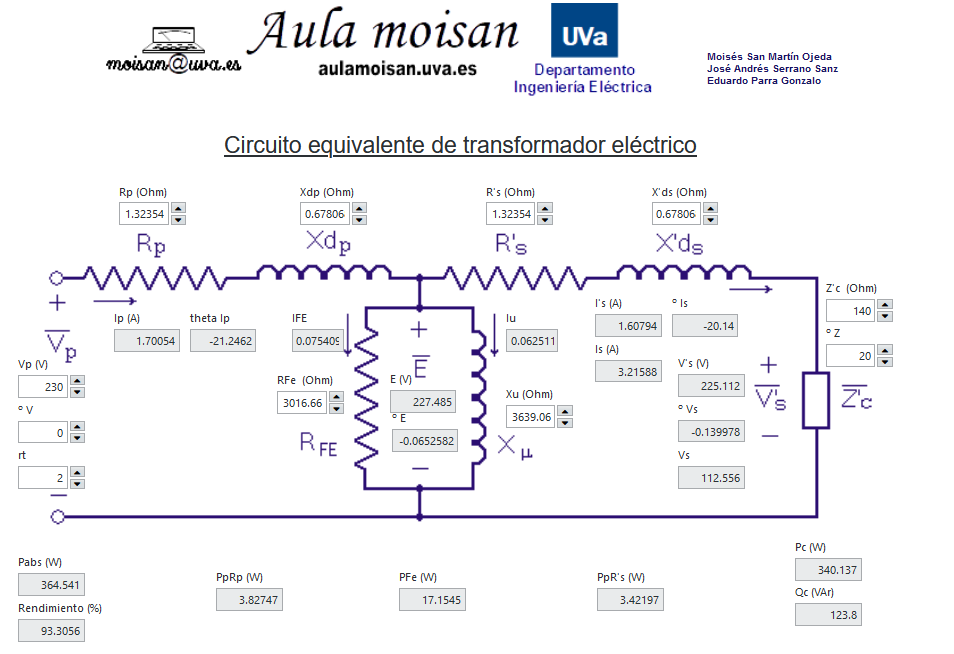

## Referencias 

Para una revisión de los conceptos y planteos de transformadores eléctricos de potencia, consúltese el capítulo 3 de transformadores del libro Máquinas Eléctricas de Fraile Mora. Al final del capítulo encontrará ejercicios para resolver mediante este esquema presentado en este cuaderno.

[Libro Máquinas Eléctricas, Fraile Mora](https://archive.org/details/maquinas-electricas-6a.-ed.-fraile-mora-jesus.)